# Figure of regularized PCA performance for all Ac group depending on #PC

LocalDataDir = '/Users/elie/Documents/DeafBats/Data';
BaseDataDir = '/Volumes/server_home/users/JulieE/DeafSalineGroup151/';
BaseCodeDir = '/Users/elie/Documents/CODE/GitHub/';
GGPath = dir('/Users/elie/Google Drive*');
Path2Paper = fullfile(GGPath.folder, GGPath.name, 'My Drive', 'BatmanData', 'Deaf Paper');

% Number of calls in each group
load(fullfile(BaseDataDir, 'Data4_DeafBats_CatCalls_UMAPMic.mat'), 'TmicAll4');
load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls2.mat'),'MicAudioGood', 'BatID');
MicAudioGood01 = MicAudioGood;
MicAudioGood01(isnan(MicAudioGood01)) = 0;
MicAudioGood01 = logical(MicAudioGood01);
IndMicAudioGood = find(MicAudioGood01);
% Get the vector SexDeaf
GGPath = dir('/Users/elie/Google Drive*');
Path2RecordingTable = fullfile(GGPath.folder, GGPath.name,'My Drive/JuvenileRecordings/DeafRecordingsNWAF155_Log.xlsx');
[~,~,RecTableData]=xlsread(Path2RecordingTable,2,'A1:k3','basic');
BatName = cell2mat(RecTableData(3,2:11));
SexDeaf =  cell(length(BatID),1);
for bat = 1:length(BatName)
    ColID = 1+ bat;
    if strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'M')
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DM'};
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'M')
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HM'};
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'F')
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HF'};
    elseif strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'F')
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DF'};
    end

end
SexDeafMic = SexDeaf(IndMicAudioGood);

Figure of all results for males

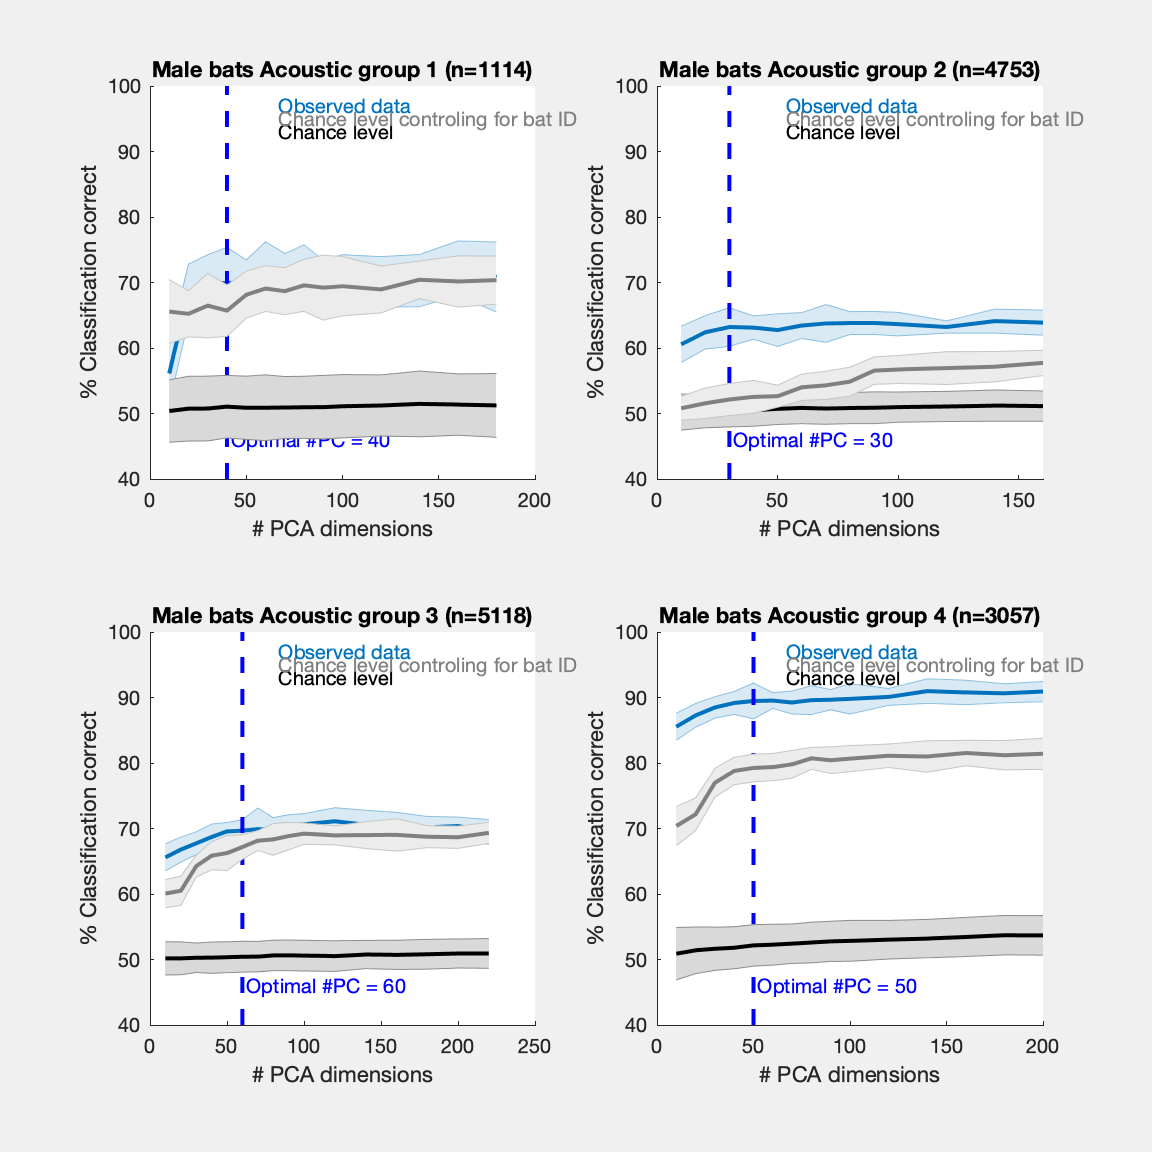

PLim = 0.001;
ColorCode = [get(groot, 'DefaultAxesColorOrder'); 0 1 1; 0.5 0.5 0.5; 1 0 0 ; 0 1 0 ; 0 0 1; 1 0 1; 0 0 0];
FIG = figure(1);
clf
set(gcf,'Visible','on')
for GR=1:4
    subplot(2,2,GR);
    load(fullfile(LocalDataDir, sprintf('DeafBats_RegularizedPermDFA_MaleAcGroup%d.mat', GR)),  'PC_val_M', 'NPC_opt_M','L_males', 'PFisher_males', 'PCC_males_mean_std', 'Lperm_males', 'PCCperm_males_mean_std', 'Lrand_males', 'PCCrand_males_mean_std', 'PC_DF_males')
    PC_val_plot = PC_val_M(1:size(PCCrand_males_mean_std,1));
    shadedErrorBar(PC_val_plot, PCC_males_mean_std(1:length(PC_val_plot),1),PCC_males_mean_std(1:length(PC_val_plot),2),{'-','color',ColorCode(1,:), 'LineWidth',2})
    xlabel('# PCA dimensions')
    ylabel('% Classification correct')
    set(gca, 'YLim', [40 100])
%     hold on
%     H=hline(50, 'k--','Chance level');
%     H.LineWidth = 2;
    hold on
    V = vline(NPC_opt_M, 'b--', sprintf('Optimal #PC = %d', NPC_opt_M));
    V.LineWidth = 2;
    hold on
    shadedErrorBar(PC_val_plot, PCCrand_males_mean_std(:,1),PCCrand_males_mean_std(:,2), {'-','Color','k', 'LineWidth',2})
    hold on
    shadedErrorBar(PC_val_plot, PCCperm_males_mean_std(:,1),PCCperm_males_mean_std(:,2), {'-', 'Color', [0.5 0.5 0.5], 'LineWidth',2})
    hold off
    XLim = get(gca,'XLim');
    text(XLim(2)/3,97, 'Observed data', 'Color', ColorCode(1,:))
    text(XLim(2)/3,93, 'Chance level', 'Color', 'k')
    text(XLim(2)/3,95, 'Chance level controling for bat ID', 'Color', [0.5 0.5 0.5])
    title(sprintf('Male bats Acoustic group %d (n=%d)', GR, sum(contains(SexDeafMic, 'M').*(TmicAll4==GR))))
    box off
%     title(sprintf('# Significant exact Fisher test (obs vs perm) at optimal #PC: %d/%d', sum(PFisher_males<PLim), length(PFisher_males)))
end
FIG.PaperOrientation = 'landscape';
FIG.Units = 'inches';
FIG.Position(3:4) = [8 8];
FIG.PaperSize = [8 8];
print(FIG,fullfile(Path2Paper,'SupFigure10_PCADFA_Males_TmicAll4.pdf'),'-dpdf','-fillpage')

Figure of all results for females

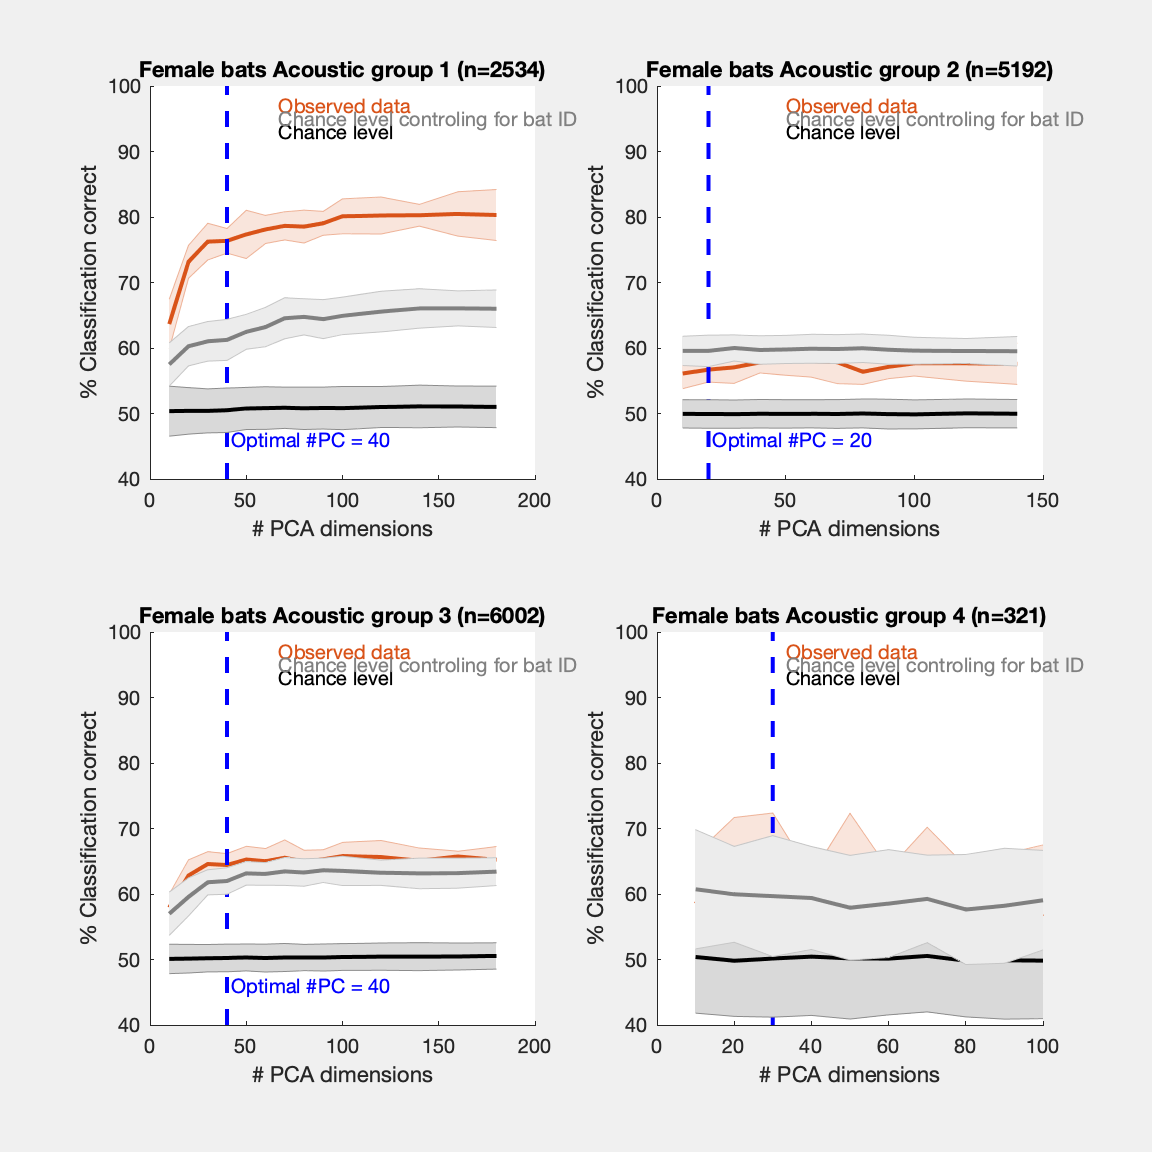

PLim = 0.001;
ColorCode = [get(groot, 'DefaultAxesColorOrder'); 0 1 1; 0.5 0.5 0.5; 1 0 0 ; 0 1 0 ; 0 0 1; 1 0 1; 0 0 0];
FIG2 = figure(2);
clf
set(gcf,'Visible','on')
for GR=1:4
    subplot(2,2,GR);
    load(fullfile(LocalDataDir, sprintf('DeafBats_RegularizedPermDFA_FemaleAcGroup%d.mat', GR)),  'PC_val_F', 'NPC_opt_F','L_females', 'PFisher_females', 'PCC_females_mean_std', 'Lperm_females', 'PCCperm_females_mean_std', 'Lrand_females', 'PCCrand_females_mean_std', 'PC_DF_females')
    PC_val_plot = PC_val_F(1:size(PCCrand_females_mean_std,1));
    shadedErrorBar(PC_val_plot, PCC_females_mean_std(1:length(PC_val_plot),1),PCC_females_mean_std(1:length(PC_val_plot),2),{'-','color',ColorCode(2,:), 'LineWidth',2})
    xlabel('# PCA dimensions')
    ylabel('% Classification correct')
    set(gca, 'YLim', [40 100])
%     hold on
%     H=hline(50, 'k--','Chance level');
%     H.LineWidth = 2;
    hold on
    V = vline(NPC_opt_F, 'b--', sprintf('Optimal #PC = %d', NPC_opt_F));
    V.LineWidth = 2;
    hold on
    shadedErrorBar(PC_val_plot, PCCrand_females_mean_std(:,1),PCCrand_females_mean_std(:,2), {'-','Color','k', 'LineWidth',2})
    hold on
    shadedErrorBar(PC_val_plot, PCCperm_females_mean_std(:,1),PCCperm_females_mean_std(:,2), {'-', 'Color', [0.5 0.5 0.5], 'LineWidth',2})
    hold off
    XLim = get(gca,'XLim');
    text(XLim(2)/3,97, 'Observed data', 'Color', ColorCode(2,:))
    text(XLim(2)/3,93, 'Chance level', 'Color', 'k')
    text(XLim(2)/3,95, 'Chance level controling for bat ID', 'Color', [0.5 0.5 0.5])
    title(sprintf('Female bats Acoustic group %d (n=%d)', GR,sum(contains(SexDeafMic, 'F').*(TmicAll4==GR))))
    box off
%     title(sprintf('# Significant exact Fisher test (obs vs perm) at optimal #PC: %d/%d', sum(PFisher_males<PLim), length(PFisher_males)))
end
FIG2.PaperOrientation = 'landscape';
FIG2.Units = 'inches';
FIG2.Position(3:4) = [8 8];
FIG2.PaperSize = [8 8];
print(FIG2,fullfile(Path2Paper,'SupFigure11_PCADFA_Females_TmicAll4.pdf'),'-dpdf','-fillpage')

Figure of optimal PC choice for males

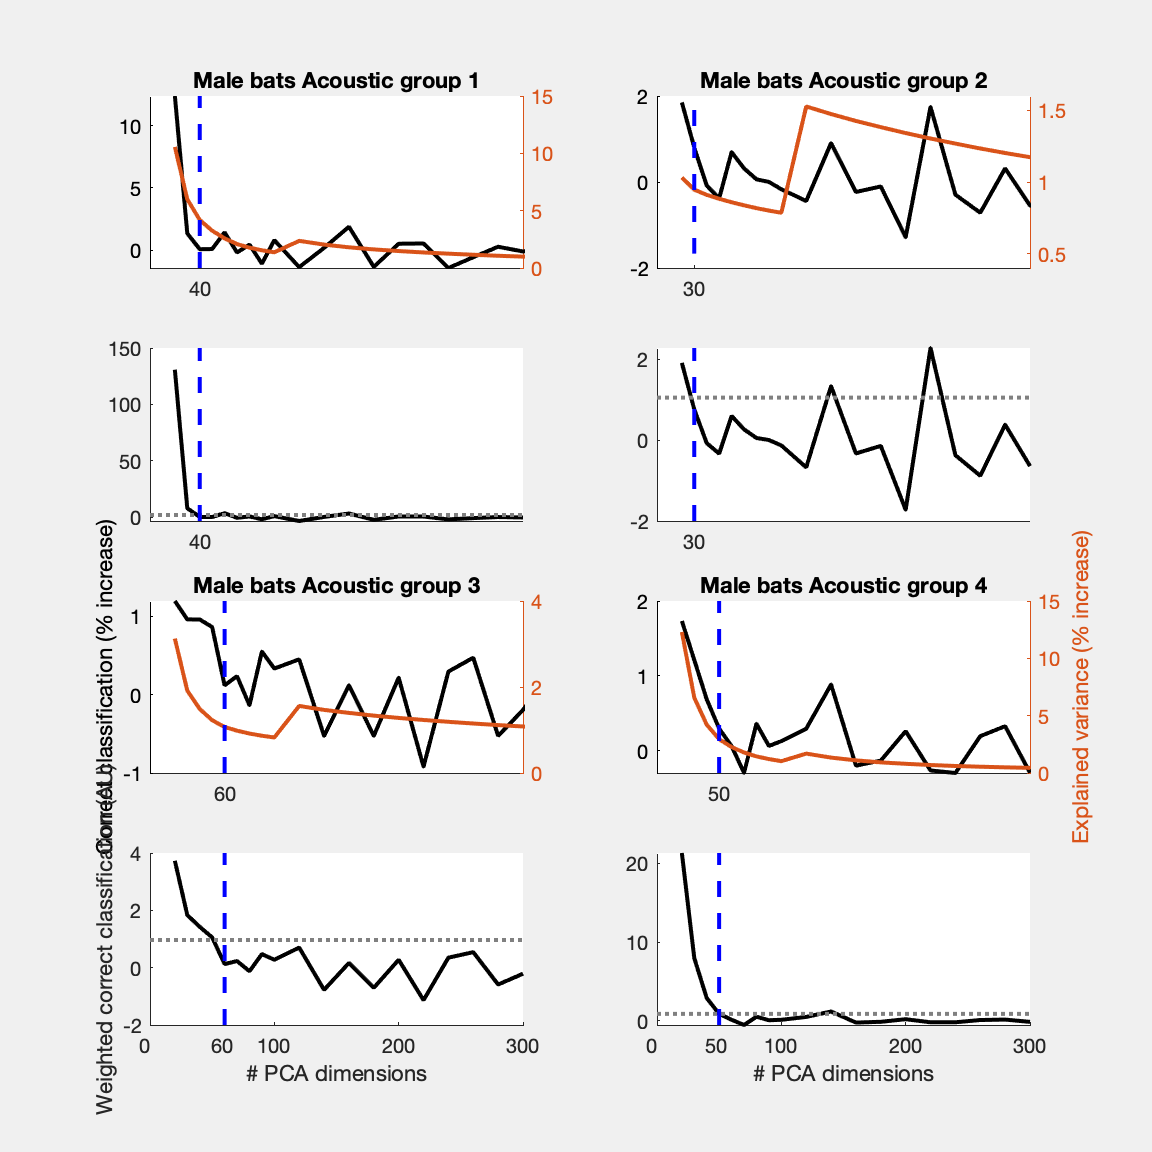

ColorCode = [get(groot, 'DefaultAxesColorOrder'); 0 1 1; 0.5 0.5 0.5; 1 0 0 ; 0 1 0 ; 0 0 1; 1 0 1; 0 0 0];
FIG3 = figure(3);
clf
set(gcf,'Visible','on')
SetFig1= [1 2 5 6]; %[1 2 5 6 9 10];
SetFig2 = [3 4 7 8]; %[3 4 7 8 11 12];
for GR=1:4
    subplot(4,2,SetFig1(GR));
    load(fullfile(LocalDataDir, sprintf('DeafBats_RegularizedPermDFA_MaleAcGroup%d.mat', GR)),  'PC_val_M', 'NPC_opt_M','L_males', 'PFisher_males', 'PCC_males_mean_std', 'Lperm_males', 'PCCperm_males_mean_std', 'Lrand_males', 'PCCrand_males_mean_std', 'PC_DF_males')
    load(fullfile(LocalDataDir, sprintf('DeafBats_PCA_MaleAcGroup%d.mat', GR)), 'PC_M', 'VarExpl_M');
    CSVarExpl_M = cumsum(VarExpl_M);
    Objective = diff(PCC_males_mean_std(:,1)) .* diff(CSVarExpl_M(PC_val_M));
    NPC_opt_ind = find(Objective-mean(PCC_males_mean_std(:,2))/2<0, 1, 'first')+1;
    NPC_opt_M = PC_val_M(NPC_opt_ind);
    PC_val_plot = PC_val_M(1:size(PCCrand_males_mean_std,1));
    plot(PC_val_M (2:end), diff(PCC_males_mean_std(:,1)),'-','color','k', 'LineWidth',2)
    if GR==3 %GR==5
        ylabel('Correct classification (% increase)')
    end
%     set(gca, 'YLim', [40 100])
    yyaxis right
    plot(PC_val_M(2:end), diff(CSVarExpl_M(PC_val_M)),'-','color',ColorCode(2,:), 'LineWidth',2)
    hold on
    if GR==4 %GR==6
        ylabel('Explained variance (% increase)')
    end
    xlim([0 300])
    hold on
    V = vline(NPC_opt_M, 'b--');
    V.LineWidth = 2;
    hold off
    title(sprintf('Male bats Acoustic group %d', GR))
    set(gca, 'XTick', NPC_opt_M, 'XTickLabels',  NPC_opt_M)
    box off

    subplot(4,2,SetFig2(GR));
    plot(PC_val_M (2:end), Objective,'-','color','k', 'LineWidth',2)
    hold on
    H=hline(mean(PCC_males_mean_std(:,2))/2);
    H.LineWidth=2;
    H.Color = [0.5 0.5 0.5];
    hold on
    xlim([0 300])
    hold on
    V = vline(NPC_opt_M, 'b--');
    V.LineWidth = 2;
    if GR==3%GR==5
        ylabel('Weighted correct classification (AU)')
        xlabel('# PCA dimensions')
        XT = get(gca, 'XTick');
        XT = [XT NPC_opt_M];
        set(gca, 'XTick', sort(XT), 'XTickLabels', sort(XT));
    elseif GR==4%GR==6
        xlabel('# PCA dimensions')
        XT = get(gca, 'XTick');
        XT = [XT NPC_opt_M];
        set(gca, 'XTick', sort(XT), 'XTickLabels', sort(XT));
    else
        set(gca, 'XTick', NPC_opt_M, 'XTickLabels',  NPC_opt_M)
    end
    hold off
    box off
%     title(sprintf('# Significant exact Fisher test (obs vs perm) at optimal #PC: %d/%d', sum(PFisher_males<PLim), length(PFisher_males)))
end
FIG3.PaperOrientation = 'landscape';
FIG3.Units = 'inches';
FIG3.Position(3:4) = [8 8];
FIG3.PaperSize = [8 8];
print(FIG3,fullfile(Path2Paper,'MethodFigure4_PCADFA_Males_TmicAll4.pdf'),'-dpdf','-fillpage')

Figure of optimal PC choice for females

ColorCode = [get(groot, 'DefaultAxesColorOrder'); 0 1 1; 0.5 0.5 0.5; 1 0 0 ; 0 1 0 ; 0 0 1; 1 0 1; 0 0 0];
FIG4 = figure(4);
clf
set(gcf,'Visible','on')
SetFig1= [1 2 5 6]; %[1 2 5 6 9 10]
SetFig2 = [3 4 7 8];%[3 4 7 8 11 12]
for GR=1:4
    subplot(4,2,SetFig1(GR));
    load(fullfile(LocalDataDir, sprintf('DeafBats_RegularizedPermDFA_FemaleAcGroup%d.mat', GR)),  'PC_val_F', 'NPC_opt_F', 'PCC_females_mean_std')
    load(fullfile(LocalDataDir, sprintf('DeafBats_PCA_FemaleAcGroup%d.mat', GR)), 'PC_F', 'VarExpl_F');
    CSVarExpl_F = cumsum(VarExpl_F);
    Objective = diff(PCC_females_mean_std(:,1)) .* diff(CSVarExpl_F(PC_val_F));
    NPC_opt_ind = find(Objective-mean(PCC_females_mean_std(:,2))/2<0, 1, 'first')+1;
    NPC_opt_F = PC_val_F(NPC_opt_ind);
    plot(PC_val_F (2:end), diff(PCC_females_mean_std(:,1)),'-','color','k', 'LineWidth',2)
    if GR==3%GR==5
        ylabel('Correct classification (% increase)')
    end
    yyaxis right
    plot(PC_val_F(2:end), diff(CSVarExpl_F(PC_val_F)),'-','color',ColorCode(2,:), 'LineWidth',2)
    hold on
    if GR==4%GR==6
        ylabel('Explained variance (% increase)')
    end
    if GR ==4
        xlim([0 100])
    else
        xlim([0 300])
    end
    hold on
    yyaxis left
    V = vline(NPC_opt_F, 'b--');
    V.LineWidth = 2;
    hold off
    title(sprintf('Female bats Acoustic group %d', GR))
    set(gca, 'XTick', NPC_opt_F, 'XTickLabels',  NPC_opt_F)
    box off

    subplot(4,2,SetFig2(GR));
    plot(PC_val_F (2:end), Objective,'-','color','k', 'LineWidth',2)
    hold on
    H=hline(mean(PCC_females_mean_std(:,2))/2);
    H.LineWidth=2;
    H.Color = [0.5 0.5 0.5];
    hold on
    if GR==4
        xlim([0 100])
    else
        xlim([0 300])
    end
    hold on
    V = vline(NPC_opt_F, 'b--');
    V.LineWidth = 2;
    if GR==3%GR==5
        ylabel('Weighted correct classification (AU)')
        xlabel('# PCA dimensions')
        XT = get(gca, 'XTick');
        XT = [XT NPC_opt_F];
        set(gca, 'XTick', sort(XT), 'XTickLabels', sort(XT));
    elseif GR==4%GR==6
        xlabel('# PCA dimensions')
        XT = get(gca, 'XTick');
        XT = [XT NPC_opt_F];
        set(gca, 'XTick', sort(XT), 'XTickLabels', sort(XT));
    else
        set(gca, 'XTick', NPC_opt_F, 'XTickLabels',  NPC_opt_F)
    end
    hold off
    box off
%     title(sprintf('# Significant exact Fisher test (obs vs perm) at optimal #PC: %d/%d', sum(PFisher_males<PLim), length(PFisher_males)))
end
FIG4.PaperOrientation = 'landscape';
FIG4.Units = 'inches';
FIG4.Position(3:4) = [8 10];
FIG4.PaperSize = [8 10];
print(FIG4,fullfile(Path2Paper,'MethodFigure5_PCADFA_Females_TmicAll4.pdf'),'-dpdf','-fillpage')